clear 
clc


addpath '.\INM'
addpath '.\SD'
addpath '.\FR'
addpath '.\functions'

load('forcing_terms.mat')
load('test_functions2.mat')
load('myFunctions.mat')

%Armijo
c1 = 1e-4;
rho = 0.5;
btmax = 50;
alpha0 = 1;

%Step for finite differences
h = 1e-8;

%Problem definition
n = 1000;
x0 = x0_t(n);
f = f16;
gradf = gf16;
Hessf = 0;

kmax = 50000;
tolgrad = 1.0E-6;
toldiffgrad = 1e-12;

% max number of iterations for the pcg
pcg_maxit = 200;

run_steepest = true;
run_fr = true;
run_newton = true;



%P5 -> Converges (with tolgrad or kmax easier)
%P13 -> Converges
%P14 -> Converge (con pcgmax=200,ci mette un botto)
%P23 

##     Run Steepest Descent

if run_steepest
    disp('***Steepest Descent: start***')
    tic
    [xk_sd, fk_sd, gradfk_norm_sd, k_sd, xseq_sd, btseq_sd, fseq_sd, gfseq_sd] = ... 
        steepest_desc_bt(x0, f, gradf, alpha0, kmax, tolgrad, c1, rho, btmax)
    
    disp('***Steepest Descent: finished')
    toc
    disp('***SD: results')
    disp('*******')
    disp(['xk: ', mat2str(xk_sd)])
    disp(['f(xk): ', mat2str(fk_sd)])
    disp(['gradf(xk): ', mat2str(gradfk_norm_sd)])
    disp(['N of iterations: ', num2str(k_sd), '/', num2str(kmax), ';'])
    %epsk_steep = norm(x_star_rose-xk_sd)
    %disp(epsk_steep)
    disp('****')
else
    disp("SD Method not runned")
end

***Steepest Descent: start***


Iteration 1 gf_norm: 977.598004
Iteration 2 gf_norm: 276.448832
Iteration 3 gf_norm: 105.683154
Iteration 4 gf_norm: 43.576570
Iteration 5 gf_norm: 21.529290
Iteration 6 gf_norm: 28.001683
Iteration 7 gf_norm: 14.698558
Iteration 8 gf_norm: 19.885062
Iteration 9 gf_norm: 11.888037
Iteration 10 gf_norm: 30.680902
Iteration 11 gf_norm: 14.254284
Iteration 12 gf_norm: 21.412813
Iteration 13 gf_norm: 11.244755
Iteration 14 gf_norm: 15.454425
Iteration 15 gf_norm: 9.431830
Iteration 16 gf_norm: 23.820714
Iteration 17 gf_norm: 11.347368
Iteration 18 gf_norm: 16.765017
Iteration 19 gf_norm: 9.149390
Iteration 20 gf_norm: 12.280180
Iteration 21 gf_norm: 19.087682
Iteration 22 gf_norm: 9.525600
Iteration 23 gf_norm: 13.620531
Iteration 24 gf_norm: 7.896303
Iteration 25 gf_norm: 21.466626
Iteration 26 gf_norm: 9.926885
Iteration 27 gf_norm: 15.015837
Iteration 28 gf_norm: 7.916306
Iteration 29 gf_norm: 10.905929
Iteration 30 gf_norm: 17.211677
Iteration 31 gf_norm: 8.380977
Iteration 32 gf_norm:

xk_sd =    -1.1071
   -0.7854
   -0.5880
   -0.4636
   -0.3805
   -0.3218
   -0.2783
   -0.2450
   -0.2187
   -0.1974


fk_sd = -427.4045

gradfk_norm_sd = 9.4604e-06

k_sd = 50000

xseq_sd =    -0.0156   -0.0176   -0.0195   -0.0214   -0.0234   -0.0272   -0.0291   -0.0330   -0.0349   -0.0426   -0.0445   -0.0483   -0.0502   -0.0540   -0.0559   -0.0635   -0.0654   -0.0692   -0.0710   -0.0748   -0.0785   -0.0804   -0.0842   -0.0860   -0.0935   -0.0953   -0.0990   -0.1009   -0.1046   -0.1082   -0.1101   -0.1137   -0.1156   -0.1192   -0.1229   -0.1247   -0.1283   -0.1301   -0.1374   -0.1392   -0.1428   -0.1446   -0.1482   -0.1517   -0.1535   -0.1571   -0.1589   -0.1659   -0.1677   -0.1712
   -0.0156   -0.0175   -0.0195   -0.0214   -0.0233   -0.0271   -0.0290   -0.0328   -0.0347   -0.0422   -0.0441   -0.0478   -0.0497   -0.0534   -0.0552   -0.0626   -0.0644   -0.0681   -0.0699   -0.0735   -0.0771   -0.0789   -0.0825   -0.0843   -0.0914   -0.0932   -0.0967   -0.0985   -0.1020   -0.1055   -0.1072   -0.1107   -0.1124   -0.1158   -0.1193   -0.1210   -0.1244   -0.1261   -0.1328   -0.1345   -0.1379   -0.1395   -0.1429   -0.1462   -0.1478   -0.1511   -0.1527   -0.1593   -0.160

btseq_sd =      7    10    10    10    10     9    10     9    10     8    10     9    10     9    10     8    10     9    10     9     9    10     9    10     8    10     9    10     9     9    10     9    10     9     9    10     9    10     8    10     9    10     9     9    10     9    10     8    10     9


fseq_sd =   -17.3053 -390.8159 -416.1825 -420.1105 -420.9294 -421.1822 -421.5075 -421.6667 -421.8556 -421.9350 -422.2743 -422.3332 -422.5207 -422.6151 -422.7313 -422.8014 -423.0107 -423.0615 -423.1812 -423.2540 -423.2703 -423.4111 -423.4630 -423.5476 -423.5647 -423.7297 -423.7566 -423.8488 -423.8966 -423.8991 -424.0107 -424.0445 -424.1104 -424.1567 -424.1744 -424.2518 -424.2885 -424.3372 -424.3667 -424.4572 -424.4818 -424.5349 -424.5704 -424.5826 -424.6456 -424.6740 -424.7135 -424.7350 -424.8093 -424.8287


gfseq_sd =   977.5980  276.4488  105.6832   43.5766   21.5293   28.0017   14.6986   19.8851   11.8880   30.6809   14.2543   21.4128   11.2448   15.4544    9.4318   23.8207   11.3474   16.7650    9.1494   12.2802   19.0877    9.5256   13.6205    7.8963   21.4666    9.9269   15.0158    7.9163   10.9059   17.2117    8.3810   12.2147    6.8971    9.0813   13.8874    7.1987   10.0442    6.1166   15.5951    7.5059   11.0402    6.1562    8.1831   12.5884    6.4691    9.0880    5.4899   14.1656    6.7893   10.0215


***Steepest Descent: finished


Elapsed time is 104.097503 seconds.


***SD: results


*******


xk: [-1.10714580957628;-0.785398101184413;-0.588002603055167;-0.46364760899836;-0.380506377112355;-0.321750554396641;-0.278299659005111;-0.244978663126864;-0.218668945873942;-0.19739555984988;-0.179853499792478;-0.165148677414627;-0.152649328395265;-0.141897054604164;-0.132551532296674;-0.124354994546761;-0.117108744566864;-0.110657221173895;-0.104876938730234;-0.099668652491162;-0.0949517063427562;-0.090659887200745;-0.086738338675985;-0.0831412318884412;-0.0798299857122373;-0.0767718912697779;-0.0739390376579402;-0.0713074647852903;-0.0688564893010446;-0.0665681637758238;-0.0644268394255535;-0.0624188099959572;-0.0605320197821069;-0.0587558227157226;-0.0570807824062647;-0.0554985052457168;-0.0540015003759682;-0.0525830616109416;-0.0512371674034187;-0.0499583957219428;-0.0487418513099314;-0.0475831032769834;-0.0464781313510029;-0.0454232794215769;-0.0444152152469108;-0.0434508953915308;-0.042527534619784;-0.0416425790985882;-0.0407936828678653;-0.03997868712329;-0.0391956019270546;-0.

f(xk): -427.404476374839


gradf(xk): 9.46038348039777e-06


N of iterations: 50000/50000;


****


**Run FR**

if run_fr
    disp('***FR: start***')
    tic
    [xk_fr, fk, gradfk_norm, k_fr, xseq_fr, btseq_fr, fseq_fr, gfseq_fr] = fletcher_reeves(x0, f, gradf, alpha0, kmax, tolgrad, c1, rho, btmax)
    
    disp('***FR: finished')
    toc
    disp('***FR: results')
    disp('*******')
    disp(['xk: ', mat2str(xk_fr)])
    disp(['f(xk): ', mat2str(fk)])
    disp(['gradf(xk): ', mat2str(gradfk_norm)])
    disp(['N of iterations: ', num2str(k_fr), '/', num2str(kmax), ';'])
    %epsk_fr = norm(x_star_rose-xk_fr)
    disp('****')
else
    disp("FR Method not runned")
end

***FR: start***


Iteration 1 gf_norm: 977.598004
Iteration 2 gf_norm: 961.365598
Iteration 3 gf_norm: 304.971323
Iteration 4 gf_norm: 221.171355
Iteration 5 gf_norm: 119.913792
Iteration 6 gf_norm: 105.643478
Iteration 7 gf_norm: 51.244851
Iteration 8 gf_norm: 30.998627
Iteration 9 gf_norm: 41.688509
Iteration 10 gf_norm: 35.002732
Iteration 11 gf_norm: 24.761345
Iteration 12 gf_norm: 31.051672
Iteration 13 gf_norm: 25.284129
Iteration 14 gf_norm: 20.662385
Iteration 15 gf_norm: 19.668198
Iteration 16 gf_norm: 26.886230
Iteration 17 gf_norm: 30.290724
Iteration 18 gf_norm: 19.683818
Iteration 19 gf_norm: 13.680675
Iteration 20 gf_norm: 10.509925
Iteration 21 gf_norm: 7.703435
Iteration 22 gf_norm: 11.550250
Iteration 23 gf_norm: 16.403147
Iteration 24 gf_norm: 24.822894
Iteration 25 gf_norm: 23.723411
Iteration 26 gf_norm: 12.813007
Iteration 27 gf_norm: 7.533641
Iteration 28 gf_norm: 9.064723
Iteration 29 gf_norm: 10.177276
Iteration 30 gf_norm: 12.529572
Iteration 31 gf_norm: 15.104773
Iteration 32 g

xk_fr =    -1.1072
   -0.7854
   -0.5880
   -0.4636
   -0.3805
   -0.3218
   -0.2783
   -0.2450
   -0.2187
   -0.1974


fk = -427.4045

gradfk_norm = 1.3258e-04

k_fr = 50000

xseq_fr =    -0.0156   -0.0232   -0.0288   -0.0338   -0.0403   -0.0460   -0.0542   -0.0600   -0.0717   -0.0861   -0.1000   -0.1213   -0.1416   -0.1587   -0.1886   -0.2227   -0.2931   -0.3410   -0.3642   -0.3784   -0.3896   -0.4075   -0.4533   -0.5509   -0.6080   -0.6611   -0.6776   -0.6908   -0.7012   -0.7292   -0.7733   -0.8060   -0.8416   -0.8581   -0.8777   -0.8916   -0.9057   -0.9155   -0.9287   -0.9357   -0.9500   -0.9601   -0.9708   -0.9794   -0.9993   -1.0034   -1.0201   -1.0302   -1.0381   -1.0466
   -0.0156   -0.0232   -0.0288   -0.0337   -0.0400   -0.0456   -0.0537   -0.0593   -0.0708   -0.0847   -0.0981   -0.1185   -0.1380   -0.1542   -0.1825   -0.2143   -0.2797   -0.3240   -0.3451   -0.3577   -0.3674   -0.3823   -0.4201   -0.5004   -0.5472   -0.5905   -0.6037   -0.6138   -0.6216   -0.6422   -0.6741   -0.6976   -0.7229   -0.7344   -0.7476   -0.7568   -0.7658   -0.7718   -0.7795   -0.7835   -0.7914   -0.7968   -0.8024   -0.8066   -0.8160   -0.8179   -0.8254   -0.8297   -0.832

btseq_fr =      7     9    10     9     9     9     9     9     8     9     9     8     9     9     8     8     8     9     9     9     9     8     8     8    10    10    10     9    10     9     9    10    10    10     9    10    10    10     9    11    10    10    10    10     9    12    10    10    10    10


fseq_fr =   -17.3053  -41.8971 -382.6172 -402.5654 -416.1439 -418.0368 -421.1811 -422.4343 -422.4555 -423.0123 -423.5985 -423.8184 -424.3008 -424.6042 -424.9160 -425.0247 -425.3113 -425.8648 -426.0672 -426.1732 -426.2496 -426.3002 -426.4019 -426.4723 -426.5193 -426.7422 -426.8086 -426.8269 -426.8425 -426.9127 -426.9319 -426.9674 -427.0721 -427.1191 -427.1424 -427.1555 -427.1850 -427.2051 -427.2134 -427.2202 -427.2373 -427.2427 -427.2515 -427.2613 -427.2630 -427.2639 -427.2847 -427.2895 -427.2952 -427.3066


gfseq_fr =   977.5980  961.3656  304.9713  221.1714  119.9138  105.6435   51.2449   30.9986   41.6885   35.0027   24.7613   31.0517   25.2841   20.6624   19.6682   26.8862   30.2907   19.6838   13.6807   10.5099    7.7034   11.5502   16.4031   24.8229   23.7234   12.8130    7.5336    9.0647   10.1773   12.5296   15.1048   15.5971   10.4346    7.8119    9.1637    9.0518    7.3564    5.8741    8.4377    8.3788    6.9479    7.0404    6.1939    6.5738    8.3536    8.3950    6.4465    5.6585    5.8386    5.4569


***FR: finished


Elapsed time is 131.821781 seconds.


***FR: results


*******


xk: [-1.10715230369109;-0.785400114830581;-0.588000955785001;-0.46364815758796;-0.380507443633395;-0.321750543283329;-0.278299404688974;-0.24497882374595;-0.218668524182595;-0.197395710096825;-0.179853621315614;-0.165148790845889;-0.152648829457839;-0.141897334559796;-0.13255074489675;-0.124355366462167;-0.117108762430307;-0.11065725682482;-0.104877252681515;-0.0996684311334411;-0.0949517322475326;-0.090659931719859;-0.0867383847838366;-0.0831412835056569;-0.0798297889388947;-0.076772022534091;-0.0739392997201983;-0.0713072799328558;-0.0688563982059438;-0.0665682682794658;-0.0644266113061989;-0.0624186684062727;-0.0605323575265324;-0.058755994832656;-0.0570805669916167;-0.0554985094041255;-0.0540017523634107;-0.052583036952433;-0.0512369325721006;-0.0499583815409752;-0.0487420099211983;-0.0475831537888836;-0.0464780991311619;-0.0454232844025827;-0.0444151995000891;-0.0434508309438914;-0.0425275169236642;-0.0416426001536876;-0.0407936340487379;-0.0399786133857812;-0.0391956580686077;-0.

f(xk): -427.404476374771


gradf(xk): 0.000132580056761072


N of iterations: 50000/50000;


****


### **Run the Newton**

if run_newton
    kmax = 100
    % fterms = @(gradf, x, k) 0.5;
    fterms = @(gradfk, k) min(0.5, sqrt(norm(gradfk)));
    % fterms = @(gradfk, k) min(0.5, norm(gradfk));
    
    % options for finite differences
    FDgrad = 'c';
    FDHess = 'fw';
    
    disp('***IN. NEWTON F.D. options***')
    disp(['FDgrad: ', FDgrad])
    disp(['FDHess: ', FDHess])
    
    disp('***Newton: start***')
    tic
    [xk, fk, gradfk_norm, k_inm, xseq, btseq, fseq, gfseq] = ...
    innewton_general(x0, f, gradf, Hessf, kmax, ...
    tolgrad, toldiffgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit)
    
    disp('***IN. newton: finished')
    toc
    disp('***newton: results')
    disp('*******')
    disp(['xk: ', mat2str(xk)])
    disp(['f(xk): ', mat2str(fk)])
    disp(['gradf(xk): ', mat2str(gradfk_norm)])
    disp(['N of iterations: ', num2str(k_inm), '/', num2str(kmax), ';'])
    %epsk_inm = norm(x_star_rose-xk)
    disp('****')
else
    disp("Newton Method not runned")
end

kmax = 100

***IN. NEWTON F.D. options***


FDgrad: c


FDHess: fw


***Newton: start***


 
Hessian PD
pcg converged at iteration 1 to a solution with relative residual 0.036.
gradfk_norm: 305.268293 
Hessian PD
pcg converged at iteration 1 to a solution with relative residual 0.1.
gradfk_norm: 31.395312 
Hessian PD
pcg converged at iteration 7 to a solution with relative residual 0.47.
gradfk_norm: 14.798145 
Hessian PD
pcg converged at iteration 12 to a solution with relative residual 0.5.
gradfk_norm: 7.325922 
Hessian PD
pcg converged at iteration 10 to a solution with relative residual 0.49.
gradfk_norm: 3.557281 
Hessian PD
pcg converged at iteration 15 to a solution with relative residual 0.46.
gradfk_norm: 1.628232 
Hessian PD
pcg converged at iteration 5 to a solution with relative residual 0.5.
gradfk_norm: 0.808398 
Hessian PD
pcg converged at iteration 9 to a solution with relative residual 0.45.
gradfk_norm: 0.359769 
Hessian PD
pcg converged at iteration 14 to a solution with relative residual 0.4.
gradfk_norm: 0.144160 
Hessian PD
pcg converged at iteration 1

xk =    -1.1071
   -0.7854
   -0.5880
   -0.4636
   -0.3805
   -0.3218
   -0.2783
   -0.2450
   -0.2187
   -0.1974


fk = -427.4045

gradfk_norm = 6.9677e-05

k_inm = 100

xseq =    -0.0020   -0.0035   -0.1347   -0.6012   -0.7554   -1.0398   -1.0473   -1.0623   -1.1005   -1.1020   -1.1068   -1.1070   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071   -1.1071
   -0.0020   -0.0035   -0.1324   -0.5490   -0.6411   -0.7843   -0.7845   -0.7848   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854  

btseq =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     6     9    23     0    12     9     9     0     7     1     8     1    24    11    28     2     6     6    29    12    22     8    13    27     9    27    28    18    25    29    32    34    35     9    24    28


fseq =  -383.6316 -417.3666 -424.1621 -426.7558 -427.1908 -427.3831 -427.3971 -427.4018 -427.4042 -427.4044 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045 -427.4045


gfseq =   305.2683   31.3953   14.7981    7.3259    3.5573    1.6282    0.8084    0.3598    0.1442    0.0463    0.0093    0.0009    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


***IN. newton: finished


Elapsed time is 16347.100203 seconds.


***newton: results


*******


xk: [-1.10714889264907;-0.785398101724204;-0.588003010205087;-0.463648126734472;-0.380506488722728;-0.321750349173781;-0.278299981456529;-0.244978613747535;-0.218669106776328;-0.197395781550774;-0.179853327144507;-0.165148527129164;-0.152649439231129;-0.141897040257238;-0.132551622184566;-0.124354904141483;-0.117108660532737;-0.110657275525346;-0.104876938107523;-0.099668680222864;-0.0949517500650693;-0.0906599532397579;-0.0867383402256552;-0.0831411492193542;-0.079830034622528;-0.076771930418997;-0.0739389965224835;-0.0713074209197267;-0.0688565456433773;-0.066568216344116;-0.0644268543314891;-0.0624188689678145;-0.0605320027334674;-0.0587558157190371;-0.0570808016636628;-0.0554985363444752;-0.0540014835496441;-0.0525830861741837;-0.0512371554758545;-0.0499584495623848;-0.0487418853902117;-0.0475831288755302;-0.0464781333444248;-0.0454233239748656;-0.0444152200494681;-0.0434509414372301;-0.0425275323856005;-0.0416425644996085;-0.0407936585384753;-0.0399786834569015;-0.039195613415212;

f(xk): -427.404476374852


gradf(xk): 6.96766771405422e-05


N of iterations: 100/100;


****


disp('===========================================================================================================================================================================')

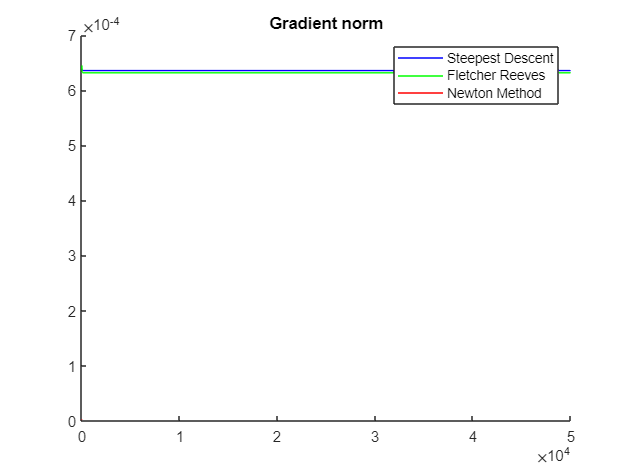

figure(1);
hold on;
title("Gradient norm")
plot(linspace(0,k_sd,k_sd), gfseq_sd, "b")
plot(linspace(0,k_fr,k_fr), gfseq_fr, "g")
plot(linspace(0,k_inm,k_inm), gfseq, "r")
legend(["Steepest Descent", "Fletcher Reeves", "Newton Method"])
hold off;

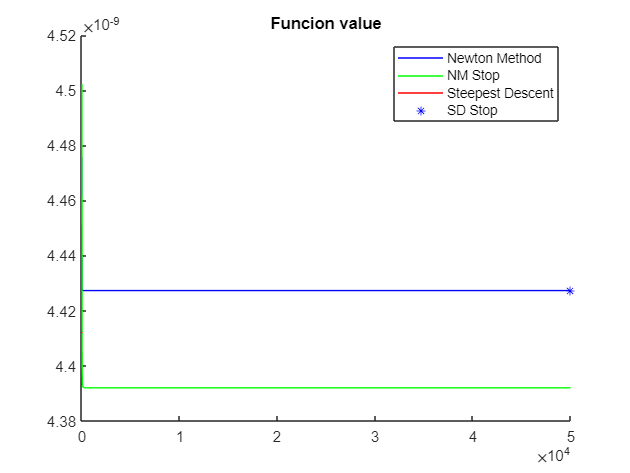

figure(2);
hold on;
title("Funcion value")
plot(linspace(0,k_sd,k_sd), fseq_sd, "b")
plot(linspace(0,k_fr,k_fr), fseq_fr, "g")
plot(linspace(0,k_inm,k_inm), fseq, "r")

plot(k_sd, fseq_sd(k_sd), "*b")
legend("Newton Method","NM Stop", "Steepest Descent", "SD Stop")
hold off;

% disp_int = [-1 1];
% 
% f1_meshgrid = @(X,Y)reshape(f([X(:),Y(:)]'),size(X));
% fcontour(f1_meshgrid, disp_int, 'Fill','on');
% hold on
% h = plot(xseq(1,:), xseq(2,:), '-*r', 'linewidth', 1, 'markersize', 5);
% hold off

% % creation of meshgrid for the contour-plot
% [X1, Y1] = meshgrid(linspace(-2, 2, 500), linspace(-2, 2, 500));
% 
% % computation of the values of f for each point of the mesh
% % Z1 = (1-X1).^2 + 100 * (Y1-X1.^2).^2;
% 
% % Plots
% 
% % simple plot
% fig1_n = figure();
% 
% % contour plot with curve levels for each point in xseq
% % [C1, ~] = contour(X1, Y1, Z1, [1, 10, 50, 100:1000:9000]);
% 
% hold on
% % plot of the points in xseq
% plot([x0(1) xseq(1, :)], [x0(2) xseq(2, :)], '-*', color="r")
% 
% hold off
% title('Inexact Newton')
